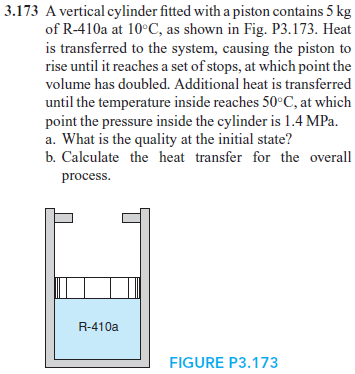

# class

u = symunit;

# state 3 (superheated vapor R-410a)

% --------------------
% given
m3 = 5*u.kg;
p3 = 1.4*u.MPa;
T3 = 50*u.Celsius;
% --------------------
% specific volume
v3 = interp1([40 60], [0.02127 0.02371], double(removeUnits(T3)))*u.m^3/u.kg;
% --------------------
% specific internal energy
u3 = interp1([40 60], [278.93 296.88], double(removeUnits(T3)))*u.kJ/u.kg;
% --------------------
% volume
V3 = m3*v3;
% --------------------

# state 2 (liquid-vapor R-410a mix) [according to Chegg, process 1-2 is isobaric...]

% --------------------
% given
m2 = m3;
p2 = 1085.7*u.kPa;
T2 = 10*u.Celsius;
V2 = V3;
v2 = v3;
% --------------------
% quality
vf2 = 0.000886*u.m^3/u.kg;
vfg2 = 0.02383*u.m^3/u.kg;
x2 = (v2-vf2)/vfg2;
% --------------------
% specific internal energy
uf2 = 72.24*u.kJ/u.kg;
ufg2 = 183.66*u.kJ/u.kg;
u2 = uf2+x2*ufg2;
% --------------------

# state 1 (liquid-vapor R-410a mix)

% --------------------
% given
m1 = m3;
p1 = 1085.7*u.kPa;
T1 = 10*u.Celsius;
V1 = 0.5*V3;
v1 = V1/m1;
% --------------------
% quality
vf1 = 0.000886*u.m^3/u.kg;
vfg1 = 0.02295*u.m^3/u.kg;
x1 = (v1-vf1)/vfg1;
x1_vpa = vpa(x1, 3) %#ok

$$x1\_vpa = 0.451$$

clear x1_vpa;
% --------------------
% specific internal energy
uf1 = 72.24*u.kJ/u.kg;
ufg1 = 183.66*u.kJ/u.kg;
u1 = uf1+x1*ufg1;
% --------------------

# work done

W_12 = rewrite(p2*V2-p1*V1, u.kJ);
W_12_vpa = vpa(W_12, 4) %#ok

$$W\_12\_vpa = 61.04\,\mathrm{kJ}$$

W_23 = 0; % since volume is constant
clear W_12_vpa;

# heat transfer

Q_12 = m2*u2-m1*u1+W_12;
Q_12_vpa = vpa(Q_12, 5) %#ok

$$Q\_12\_vpa = 479.07\,\mathrm{kJ}$$

Q_23 = m3*u3-m2*u2;
Q_23_vpa = vpa(Q_23, 5) %#ok

$$Q\_23\_vpa = 245.8\,\mathrm{kJ}$$

clear Q_12_vpa Q_23_vpa;